Problem 17

clear
A=[ts(12,36,40) ts(12,36,56) ts(12,37,12) ts(12,37,27) ts(12,37,44) ts(12,37,59) ts(12,38,14)];
B=[ts(11,59,59) ts(12,0,02) ts(11,59,57) ts(12,0,7) ts(12,0,2) ts(11,59,56) ts(12,0,3)];
C=[ts(15,50,45) ts(15,51,43) ts(15,53,41) ts(15,53,39) ts(15,54,37) ts(15,55,35) ts(15,56,33)];
D=[ts(12,3,59) ts(12,2,52) ts(12,1,45) ts(12,0,38) ts(11,59,31) ts(11,58,24) ts(11,57,17)];
E=[ts(12,3,59) ts(12,2,49) ts(12,1,54) ts(12,1,52) ts(12,1,32) ts(12,1,22) ts(12,1,12)];

plot of deviation from the first reading of five clocks in seven days of a week

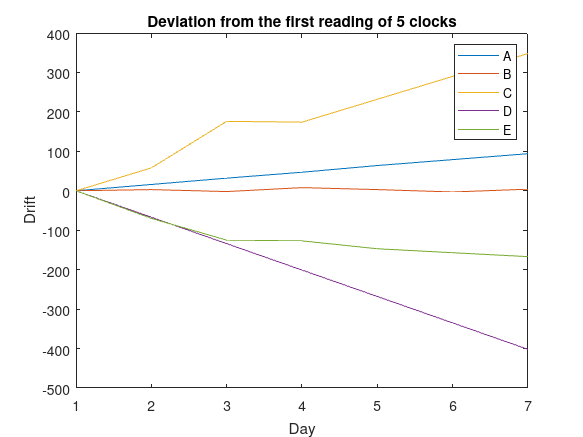

plot([(A-A(1))' (B-B(1))' (C-C(1))' (D-D(1))' (E-E(1))'])
title('Deviation from the first reading of 5 clocks')
legend('A','B','C','D','E')
xlabel('Day'), ylabel('Drift')

standard deviation

std([A' B' C' D' E'])

ans =    33.9502    3.8048  122.6905  144.7365   59.1121


#### Conclusion: Clock B is the best, D is the worst

% convert hh:MM:ss into seconds
function sec = ts(h,m,s)
    sec = h*3600 + m*60 + s;
end